## **Nastro di Moebius**

Imposto le variabili della superficie

u= linspace(0,2*pi, 100)

u =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


v= linspace(-1,1, 100)

v =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


Definisco una griglia per le variabili U e V

[U, V] = meshgrid(u, v)

U =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099
         0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3

V =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0.9798   -0

Definisco le componenti

X=(2 - V .* sin(U / 2)) .* sin(U)

X =          0    0.1289    0.2612    0.3965    0.5341    0.6734    0.8137    0.9543    1.0945    1.2336    1.3708    1.5054    1.6366    1.7637    1.8859    2.0024    2.1126    2.2157    2.3110    2.3980    2.4760    2.5444    2.6026    2.6503    2.6870    2.7124    2.7260    2.7277    2.7173    2.6947    2.6598    2.6126    2.5533    2.4821    2.3990    2.3045    2.1990    2.0827    1.9564    1.8205    1.6756    1.5225    1.3618    1.1943    1.0209    0.8423    0.6596    0.4735    0.2851    0.0952
         0    0.1288    0.2611    0.3961    0.5334    0.6724    0.8122    0.9524    1.0920    1.2305    1.3671    1.5010    1.6315    1.7578    1.8791    1.9949    2.1042    2.2065    2.3011    2.3873    2.4645    2.5322    2.5898    2.6370    2.6731    2.6980    2.7112    2.7126    2.7020    2.6792    2.6442    2.5971    2.5380    2.4669    2.3842    2.2901    2.1851    2.0695    1.9438    1.8087    1.6647    1.5125    1.3528    1.1864    1.0141    0.8367    0.6552    0.4703    0.2831    0

Y=(2 - V .* sin(U / 2)) .* cos(U)

Y =     2.0000    2.0276    2.0468    2.0572    2.0584    2.0503    2.0324    2.0048    1.9672    1.9195    1.8618    1.7941    1.7165    1.6291    1.5321    1.4259    1.3108    1.1871    1.0554    0.9161    0.7699    0.6173    0.4589    0.2956    0.1280   -0.0430   -0.2167   -0.3922   -0.5686   -0.7450   -0.9206   -1.0943   -1.2655   -1.4330   -1.5961   -1.7538   -1.9054   -2.0500   -2.1867   -2.3149   -2.4339   -2.5429   -2.6415   -2.7289   -2.8048   -2.8687   -2.9203   -2.9592   -2.9853   -2.9984
    2.0000    2.0270    2.0456    2.0553    2.0560    2.0472    2.0289    2.0008    1.9627    1.9147    1.8567    1.7888    1.7110    1.6236    1.5266    1.4205    1.3056    1.1822    1.0509    0.9121    0.7663    0.6143    0.4567    0.2941    0.1273   -0.0428   -0.2155   -0.3900   -0.5654   -0.7407   -0.9152   -1.0879   -1.2578   -1.4243   -1.5862   -1.7429   -1.8934   -2.0369   -2.1727   -2.2999   -2.4180   -2.5262   -2.6240   -2.7108   -2.7861   -2.8495   -2.9007   -2.9393   -2.9652   -2

Z=V .* cos(U / 2)

Z =    -1.0000   -0.9995   -0.9980   -0.9955   -0.9920   -0.9874   -0.9819   -0.9754   -0.9679   -0.9595   -0.9501   -0.9397   -0.9284   -0.9161   -0.9029   -0.8888   -0.8738   -0.8580   -0.8413   -0.8237   -0.8053   -0.7861   -0.7660   -0.7453   -0.7237   -0.7015   -0.6785   -0.6549   -0.6306   -0.6056   -0.5801   -0.5539   -0.5272   -0.5000   -0.4723   -0.4441   -0.4154   -0.3863   -0.3569   -0.3271   -0.2969   -0.2665   -0.2358   -0.2048   -0.1736   -0.1423   -0.1108   -0.0792   -0.0476   -0.0159
   -0.9798   -0.9793   -0.9778   -0.9754   -0.9719   -0.9675   -0.9621   -0.9557   -0.9484   -0.9401   -0.9309   -0.9207   -0.9096   -0.8976   -0.8847   -0.8709   -0.8562   -0.8407   -0.8243   -0.8070   -0.7890   -0.7702   -0.7506   -0.7302   -0.7091   -0.6873   -0.6648   -0.6416   -0.6178   -0.5934   -0.5683   -0.5427   -0.5166   -0.4899   -0.4627   -0.4351   -0.4070   -0.3785   -0.3497   -0.3205   -0.2909   -0.2611   -0.2310   -0.2007   -0.1701   -0.1394   -0.1086   -0.0776   -0.0466   -0

Apro ambiente figure e plotto la superficie

figure
surf(X, Y, Z, "EdgeColor","none")
colormap("autumn")
shading interp

Gestisco dettagli

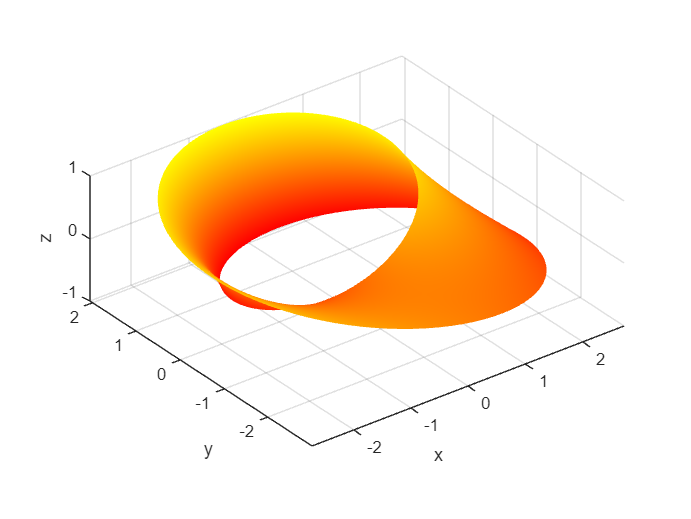

axis equal
xlabel("x")
ylabel("y")
zlabel("z")
view(3)

Aggiunta grafico operazione limite

Definisco le variabili

x=linspace(0, 2*pi, 100)

x =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


y=linspace(-1, 1, 100)

y =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


Definisco le funzioni

f1=ones(size(y))

f1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


f2=2*pi*ones(size(x))

f2 =     6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832


f3=-1*f1

f3 =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


f4=0*f2

f4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Plotto

figure
hold on
plot(x, f1, 'k')
plot(f2, y, 'k')
plot(x, f3, 'k')
plot(f4,y, 'k')

Gestisco assi

axis equal

xticks=[0,2*pi]

xticks =          0    6.2832


xtick_lab={'0', '2\pi'}

xtick_lab = 1×2 cell array
    {'0'}    {'2\pi'}


yticks= [-1, 1]

yticks =     -1     1


ytick_lab={'-1', '1'}

ytick_lab = 1×2 cell array
    {'-1'}    {'1'}


set(gca, 'XTick', xticks, 'XTickLabel', xtick_lab)
set(gca, 'YTick', yticks, 'YTickLabel', ytick_lab)

Aggiungo le frecce

a1=[-0.5, 0]

a1 =    -0.5000         0


a2=[0.5,0]

a2 =     0.5000         0


quiver(0.5, 0, a1(1), a1(2),'k', 'LineWidth', 0.5, 'MaxHeadSize', 1.5)
quiver(2*pi-0.5, 0, a2(1), a2(2),'k', 'LineWidth', 0.5, 'MaxHeadSize', 1.5)

Aggiungo etichette

text(0.35, 0.2, '$0^+$', 'Interpreter', 'latex', 'Color', 'k') 
text(2*pi-0.5, 0.2, '$2\pi^-$', 'Interpreter', 'latex', 'Color', 'k')
xlabel("u")
ylabel("<")
hold off

## **Paraboloide**

**Plot del paraboloide** 

Definisco le variabili e parametrizzo la superficie

x1= linspace(-1.5, 1.5, 100)

x1 =    -1.5000   -1.4697   -1.4394   -1.4091   -1.3788   -1.3485   -1.3182   -1.2879   -1.2576   -1.2273   -1.1970   -1.1667   -1.1364   -1.1061   -1.0758   -1.0455   -1.0152   -0.9848   -0.9545   -0.9242   -0.8939   -0.8636   -0.8333   -0.8030   -0.7727   -0.7424   -0.7121   -0.6818   -0.6515   -0.6212   -0.5909   -0.5606   -0.5303   -0.5000   -0.4697   -0.4394   -0.4091   -0.3788   -0.3485   -0.3182   -0.2879   -0.2576   -0.2273   -0.1970   -0.1667   -0.1364   -0.1061   -0.0758   -0.0455   -0.0152


y1= linspace(-1.5, 1.5, 100)

y1 =    -1.5000   -1.4697   -1.4394   -1.4091   -1.3788   -1.3485   -1.3182   -1.2879   -1.2576   -1.2273   -1.1970   -1.1667   -1.1364   -1.1061   -1.0758   -1.0455   -1.0152   -0.9848   -0.9545   -0.9242   -0.8939   -0.8636   -0.8333   -0.8030   -0.7727   -0.7424   -0.7121   -0.6818   -0.6515   -0.6212   -0.5909   -0.5606   -0.5303   -0.5000   -0.4697   -0.4394   -0.4091   -0.3788   -0.3485   -0.3182   -0.2879   -0.2576   -0.2273   -0.1970   -0.1667   -0.1364   -0.1061   -0.0758   -0.0455   -0.0152


[X1, Y1]= meshgrid(x1,y1)

X1 =    -1.5000   -1.4697   -1.4394   -1.4091   -1.3788   -1.3485   -1.3182   -1.2879   -1.2576   -1.2273   -1.1970   -1.1667   -1.1364   -1.1061   -1.0758   -1.0455   -1.0152   -0.9848   -0.9545   -0.9242   -0.8939   -0.8636   -0.8333   -0.8030   -0.7727   -0.7424   -0.7121   -0.6818   -0.6515   -0.6212   -0.5909   -0.5606   -0.5303   -0.5000   -0.4697   -0.4394   -0.4091   -0.3788   -0.3485   -0.3182   -0.2879   -0.2576   -0.2273   -0.1970   -0.1667   -0.1364   -0.1061   -0.0758   -0.0455   -0.0152
   -1.5000   -1.4697   -1.4394   -1.4091   -1.3788   -1.3485   -1.3182   -1.2879   -1.2576   -1.2273   -1.1970   -1.1667   -1.1364   -1.1061   -1.0758   -1.0455   -1.0152   -0.9848   -0.9545   -0.9242   -0.8939   -0.8636   -0.8333   -0.8030   -0.7727   -0.7424   -0.7121   -0.6818   -0.6515   -0.6212   -0.5909   -0.5606   -0.5303   -0.5000   -0.4697   -0.4394   -0.4091   -0.3788   -0.3485   -0.3182   -0.2879   -0.2576   -0.2273   -0.1970   -0.1667   -0.1364   -0.1061   -0.0758   -0.0455   -

Y1 =    -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -1.4697   -

z1= (X1.^2+Y1.^2)

z1 =     4.5000    4.4100    4.3219    4.2355    4.1511    4.0684    3.9876    3.9086    3.8315    3.7562    3.6827    3.6111    3.5413    3.4734    3.4073    3.3430    3.2805    3.2199    3.1612    3.1042    3.0491    2.9959    2.9444    2.8949    2.8471    2.8012    2.7571    2.7149    2.6745    2.6359    2.5992    2.5643    2.5312    2.5000    2.4706    2.4431    2.4174    2.3935    2.3714    2.3512    2.3329    2.3163    2.3017    2.2888    2.2778    2.2686    2.2612    2.2557    2.2521    2.2502
    4.4100    4.3200    4.2319    4.1455    4.0611    3.9784    3.8976    3.8186    3.7415    3.6662    3.5927    3.5211    3.4513    3.3834    3.3173    3.2530    3.1905    3.1299    3.0712    3.0142    2.9591    2.9059    2.8545    2.8049    2.7571    2.7112    2.6671    2.6249    2.5845    2.5459    2.5092    2.4743    2.4412    2.4100    2.3806    2.3531    2.3274    2.3035    2.2815    2.2612    2.2429    2.2264    2.2117    2.1988    2.1878    2.1786    2.1713    2.1657    2.1621    

Plotto

figure
hold on
i1= surf(x1, y1, z1, "EdgeColor","none", "FaceAlpha",0.5)

i1 =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 0.5000
           XData: [-1.5000 -1.4697 -1.4394 -1.4091 -1.3788 -1.3485 -1.3182 -1.2879 -1.2576 -1.2273 -1.1970 -1.1667 -1.1364 -1.1061 -1.0758 -1.0455 -1.0152 -0.9848 -0.9545 -0.9242 -0.8939 -0.8636 -0.8333 -0.8030 -0.7727 -0.7424 -0.7121 … ] (1×100 double)
           YData: [-1.5000 -1.4697 -1.4394 -1.4091 -1.3788 -1.3485 -1.3182 -1.2879 -1.2576 -1.2273 -1.1970 -1.1667 -1.1364 -1.1061 -1.0758 -1.0455 -1.0152 -0.9848 -0.9545 -0.9242 -0.8939 -0.8636 -0.8333 -0.8030 -0.7727 -0.7424 -0.7121 … ] (1×100 double)
           ZData: [100×100 double]
           CData: [100×100 double]

  Show 

colormap("autumn")
shading interp

**Plot del campo vettoriale**

Definisco il dominio del campo

x11=linspace(-1, 1, 5)

x11 =    -1.0000   -0.5000         0    0.5000    1.0000


y11=linspace(-1, 1, 5)

y11 =    -1.0000   -0.5000         0    0.5000    1.0000


[X11, Y11]= meshgrid(x11,y11)

X11 =    -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000


Y11 =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
         0         0         0         0         0
    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    1.0000    1.0000    1.0000    1.0000


z11= (X11.^2+Y11.^2)

z11 =     2.0000    1.2500    1.0000    1.2500    2.0000
    1.2500    0.5000    0.2500    0.5000    1.2500
    1.0000    0.2500         0    0.2500    1.0000
    1.2500    0.5000    0.2500    0.5000    1.2500
    2.0000    1.2500    1.0000    1.2500    2.0000


Definisco $\nu$ entrante

Pni_x= -2*X11 

Pni_x =      2     1     0    -1    -2
     2     1     0    -1    -2
     2     1     0    -1    -2
     2     1     0    -1    -2
     2     1     0    -1    -2


Pnni_x=Pni_x/norm(Pni_x, 'fro')

Pnni_x =     0.2828    0.1414         0   -0.1414   -0.2828
    0.2828    0.1414         0   -0.1414   -0.2828
    0.2828    0.1414         0   -0.1414   -0.2828
    0.2828    0.1414         0   -0.1414   -0.2828
    0.2828    0.1414         0   -0.1414   -0.2828


Pni_y=-2*Y11

Pni_y =      2     2     2     2     2
     1     1     1     1     1
     0     0     0     0     0
    -1    -1    -1    -1    -1
    -2    -2    -2    -2    -2


Pnni_y=Pni_y/norm(Pni_y, 'fro')

Pnni_y =     0.2828    0.2828    0.2828    0.2828    0.2828
    0.1414    0.1414    0.1414    0.1414    0.1414
         0         0         0         0         0
   -0.1414   -0.1414   -0.1414   -0.1414   -0.1414
   -0.2828   -0.2828   -0.2828   -0.2828   -0.2828


Pni_z=ones(size(X11))

Pni_z =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


Pnni_z=Pni_z/ norm(Pni_z, 'fro')

Pnni_z =     0.2000    0.2000    0.2000    0.2000    0.2000
    0.2000    0.2000    0.2000    0.2000    0.2000
    0.2000    0.2000    0.2000    0.2000    0.2000
    0.2000    0.2000    0.2000    0.2000    0.2000
    0.2000    0.2000    0.2000    0.2000    0.2000


Definisco $\nu$ uscente

Pnni1_x=-Pnni_x

Pnni1_x =    -0.2828   -0.1414         0    0.1414    0.2828
   -0.2828   -0.1414         0    0.1414    0.2828
   -0.2828   -0.1414         0    0.1414    0.2828
   -0.2828   -0.1414         0    0.1414    0.2828
   -0.2828   -0.1414         0    0.1414    0.2828


Pnni1_y=-Pnni_y

Pnni1_y =    -0.2828   -0.2828   -0.2828   -0.2828   -0.2828
   -0.1414   -0.1414   -0.1414   -0.1414   -0.1414
         0         0         0         0         0
    0.1414    0.1414    0.1414    0.1414    0.1414
    0.2828    0.2828    0.2828    0.2828    0.2828


Pnni1_z=-Pnni_z

Pnni1_z =    -0.2000   -0.2000   -0.2000   -0.2000   -0.2000
   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000
   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000
   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000
   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000


Plot

i2=quiver3(X11, Y11, z11, Pnni_x, Pnni_y, Pnni_z, 'Color','r', 'MaxHeadSize', 1.3, 'AutoScale', 'on', AutoScaleFactor=1.3, LineWidth= 1.5)

i2 =   Quiver with properties:

        Color: [1 0 0]
    LineStyle: '-'
    LineWidth: 1.5000
        XData: [5×5 double]
        YData: [5×5 double]
        ZData: [5×5 double]
        UData: [5×5 double]
        VData: [5×5 double]
        WData: [5×5 double]

  Show all properties


i3=quiver3(X11, Y11, z11, Pnni1_x, Pnni1_y, Pnni1_z, 'Color','b', 'MaxHeadSize', 1.3, 'AutoScale','on', AutoScaleFactor=1.1, LineWidth= 1.3)

i3 =   Quiver with properties:

        Color: [0 0 1]
    LineStyle: '-'
    LineWidth: 1.3000
        XData: [5×5 double]
        YData: [5×5 double]
        ZData: [5×5 double]
        UData: [5×5 double]
        VData: [5×5 double]
        WData: [5×5 double]

  Show all properties


**Aggiustamenti**

Assi

grid on
axis tight
lim = 3

lim = 3

axis([-lim lim -lim lim -1 4])
view(3)

Legenda

legend([i1, i2, i3], {'Paraboloide di equazione $z=x^2+y^2$', 'Campo vettoriale di $\nu(u,v)$ (\textit{Sopra})', 'Campo vettoriale di $-\nu(u,v)$ (\textit{Sotto})'}, 'Location', 'best', 'FontSize', 8, 'Interpreter','latex')

Chiudo hold

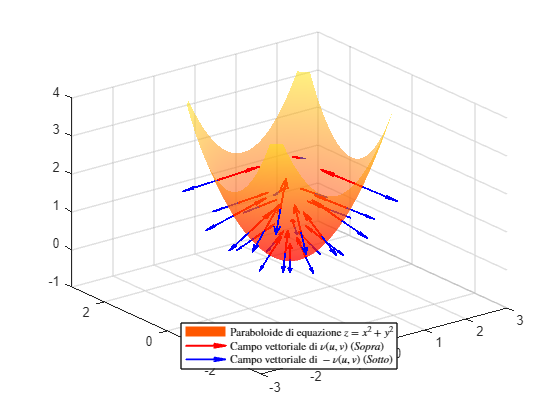

hold off

## **Guscio sferico di raggio R**

**Plot del guscio sferico**

Imposto R

R=2

R = 2

Definisco le variabili

theta= linspace(0, 2*pi, 30)

theta =          0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.7333    1.9500    2.1666    2.3833    2.5999    2.8166    3.0333    3.2499    3.4666    3.6832    3.8999    4.1166    4.3332    4.5499    4.7666    4.9832    5.1999    5.4165    5.6332    5.8499    6.0665    6.2832


phi= linspace(0, pi, 30)

phi =          0    0.1083    0.2167    0.3250    0.4333    0.5417    0.6500    0.7583    0.8666    0.9750    1.0833    1.1916    1.3000    1.4083    1.5166    1.6250    1.7333    1.8416    1.9500    2.0583    2.1666    2.2749    2.3833    2.4916    2.5999    2.7083    2.8166    2.9249    3.0333    3.1416


[Theta, Phi]= meshgrid(theta, phi)

Theta =          0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.7333    1.9500    2.1666    2.3833    2.5999    2.8166    3.0333    3.2499    3.4666    3.6832    3.8999    4.1166    4.3332    4.5499    4.7666    4.9832    5.1999    5.4165    5.6332    5.8499    6.0665    6.2832
         0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.7333    1.9500    2.1666    2.3833    2.5999    2.8166    3.0333    3.2499    3.4666    3.6832    3.8999    4.1166    4.3332    4.5499    4.7666    4.9832    5.1999    5.4165    5.6332    5.8499    6.0665    6.2832
         0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.7333    1.9500    2.1666    2.3833    2.5999    2.8166    3.0333    3.2499    3.4666    3.6832    3.8999    4.1166    4.3332    4.5499    4.7666    4.9832    5.1999    5.4165    5.6332    5.8499    6.0665    6.2832
         0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.733

Phi =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083    0.1083
    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167
    0.3250    0.3250    0.3250    0.3250    0.3250    0.3250    0.3250    0.3250    0.3250 

Definisco le equazioni parametriche

x2=R*sin(Phi).*cos(Theta)

x2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2162    0.2112    0.1963    0.1721    0.1400    0.1013    0.0578    0.0117   -0.0350   -0.0800   -0.1213   -0.1570   -0.1853   -0.2049   -0.2150   -0.2150   -0.2049   -0.1853   -0.1570   -0.1213   -0.0800   -0.0350    0.0117    0.0578    0.1013    0.1400    0.1721    0.1963    0.2112    0.2162
    0.4299    0.4199    0.3902    0.3423    0.2783    0.2014    0.1150    0.0233   -0.0696   -0.1591   -0.2413   -0.3121   -0.3684   -0.4074   -0.4274   -0.4274   -0.4074   -0.3684   -0.3121   -0.2413   -0.1591   -0.0696    0.0233    0.1150    0.2014    0.2783    0.3423    0.3902    0.4199    0.4299
    0.6386    0.6237    0.5796    0.5084    0.4134    0.2991    0.1708    0.0346   -0.1033  

y2=R*sin(Phi).*sin(Theta)

y2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0465    0.0908    0.1309    0.1648    0.1910    0.2084    0.2159    0.2134    0.2009    0.1790    0.1487    0.1115    0.0690    0.0234   -0.0234   -0.0690   -0.1115   -0.1487   -0.1790   -0.2009   -0.2134   -0.2159   -0.2084   -0.1910   -0.1648   -0.1309   -0.0908   -0.0465   -0.0000
         0    0.0924    0.1805    0.2602    0.3277    0.3799    0.4143    0.4293    0.4243    0.3994    0.3559    0.2957    0.2217    0.1373    0.0465   -0.0465   -0.1373   -0.2217   -0.2957   -0.3559   -0.3994   -0.4243   -0.4293   -0.4143   -0.3799   -0.3277   -0.2602   -0.1805   -0.0924   -0.0000
         0    0.1373    0.2681    0.3865    0.4867    0.5642    0.6153    0.6377    0.6302  

z2=R*cos(Phi)

z2 =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883    1.9883
    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532    1.9532
    1.8953    1.8953    1.8953    1.8953    1.8953    1.8953    1.8953    1.8953    1.8953  

Plotto il guscio sferico

figure
hold on
grid on
h1=surf(x2, y2, z2, "EdgeColor","none", FaceAlpha=0.5)

h1 =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 0.5000
           XData: [30×30 double]
           YData: [30×30 double]
           ZData: [30×30 double]
           CData: [30×30 double]

  Show all properties


colormap("autumn")
shading interp

**Plot del campo vettoriale**

Definisco il dominio del campo

theta1= linspace(0,2*pi, 10)

theta1 =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832


phi1= linspace(0,pi, 10)

phi1 =          0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416


[Theta1, Phi1]= meshgrid(theta1, phi1)

Theta1 =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832
         0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869  

Phi1 =          0         0         0         0         0         0         0         0         0         0
    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491
    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981
    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472
    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963
    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453
    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944
    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435
    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    

x21=R*sin(Phi1).*cos(Theta1)

x21 =          0         0         0         0         0         0         0         0         0         0
    0.6840    0.5240    0.1188   -0.3420   -0.6428   -0.6428   -0.3420    0.1188    0.5240    0.6840
    1.2856    0.9848    0.2232   -0.6428   -1.2080   -1.2080   -0.6428    0.2232    0.9848    1.2856
    1.7321    1.3268    0.3008   -0.8660   -1.6276   -1.6276   -0.8660    0.3008    1.3268    1.7321
    1.9696    1.5088    0.3420   -0.9848   -1.8508   -1.8508   -0.9848    0.3420    1.5088    1.9696
    1.9696    1.5088    0.3420   -0.9848   -1.8508   -1.8508   -0.9848    0.3420    1.5088    1.9696
    1.7321    1.3268    0.3008   -0.8660   -1.6276   -1.6276   -0.8660    0.3008    1.3268    1.7321
    1.2856    0.9848    0.2232   -0.6428   -1.2080   -1.2080   -0.6428    0.2232    0.9848    1.2856
    0.6840    0.5240    0.1188   -0.3420   -0.6428   -0.6428   -0.3420    0.1188    0.5240    0.6840
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0

y21=R*sin(Phi1).*sin(Theta1)

y21 =          0         0         0         0         0         0         0         0         0         0
         0    0.4397    0.6736    0.5924    0.2340   -0.2340   -0.5924   -0.6736   -0.4397   -0.0000
         0    0.8264    1.2660    1.1133    0.4397   -0.4397   -1.1133   -1.2660   -0.8264   -0.0000
         0    1.1133    1.7057    1.5000    0.5924   -0.5924   -1.5000   -1.7057   -1.1133   -0.0000
         0    1.2660    1.9397    1.7057    0.6736   -0.6736   -1.7057   -1.9397   -1.2660   -0.0000
         0    1.2660    1.9397    1.7057    0.6736   -0.6736   -1.7057   -1.9397   -1.2660   -0.0000
         0    1.1133    1.7057    1.5000    0.5924   -0.5924   -1.5000   -1.7057   -1.1133   -0.0000
         0    0.8264    1.2660    1.1133    0.4397   -0.4397   -1.1133   -1.2660   -0.8264   -0.0000
         0    0.4397    0.6736    0.5924    0.2340   -0.2340   -0.5924   -0.6736   -0.4397   -0.0000
         0    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0

z21=R*cos(Phi1)

z21 =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.8794    1.8794    1.8794    1.8794    1.8794    1.8794    1.8794    1.8794    1.8794    1.8794
    1.5321    1.5321    1.5321    1.5321    1.5321    1.5321    1.5321    1.5321    1.5321    1.5321
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.3473    0.3473    0.3473    0.3473    0.3473    0.3473    0.3473    0.3473    0.3473    0.3473
   -0.3473   -0.3473   -0.3473   -0.3473   -0.3473   -0.3473   -0.3473   -0.3473   -0.3473   -0.3473
   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -1.5321   -1.5321   -1.5321   -1.5321   -1.5321   -1.5321   -1.5321   -1.5321   -1.5321   -1.5321
   -1.8794   -1.8794   -1.8794   -1.8794   -1.8794   -1.8794   -1.8794   -1.8794   -1.8794   -1.8794
   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2

Definisco $\nu$ entrante

ni_x=-R^2.*(sin(Phi1)).^2.*cos(Theta1)

ni_x =          0         0         0         0         0         0         0         0         0         0
   -0.4679   -0.3584   -0.0813    0.2340    0.4397    0.4397    0.2340   -0.0813   -0.3584   -0.4679
   -1.6527   -1.2660   -0.2870    0.8264    1.5530    1.5530    0.8264   -0.2870   -1.2660   -1.6527
   -3.0000   -2.2981   -0.5209    1.5000    2.8191    2.8191    1.5000   -0.5209   -2.2981   -3.0000
   -3.8794   -2.9718   -0.6736    1.9397    3.6454    3.6454    1.9397   -0.6736   -2.9718   -3.8794
   -3.8794   -2.9718   -0.6736    1.9397    3.6454    3.6454    1.9397   -0.6736   -2.9718   -3.8794
   -3.0000   -2.2981   -0.5209    1.5000    2.8191    2.8191    1.5000   -0.5209   -2.2981   -3.0000
   -1.6527   -1.2660   -0.2870    0.8264    1.5530    1.5530    0.8264   -0.2870   -1.2660   -1.6527
   -0.4679   -0.3584   -0.0813    0.2340    0.4397    0.4397    0.2340   -0.0813   -0.3584   -0.4679
   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -

nni_x=ni_x/norm(ni_x)

nni_x =          0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0208   -0.0047    0.0136    0.0255    0.0255    0.0136   -0.0047   -0.0208   -0.0272
   -0.0959   -0.0735   -0.0167    0.0479    0.0901    0.0901    0.0479   -0.0167   -0.0735   -0.0959
   -0.1741   -0.1334   -0.0302    0.0870    0.1636    0.1636    0.0870   -0.0302   -0.1334   -0.1741
   -0.2251   -0.1724   -0.0391    0.1126    0.2115    0.2115    0.1126   -0.0391   -0.1724   -0.2251
   -0.2251   -0.1724   -0.0391    0.1126    0.2115    0.2115    0.1126   -0.0391   -0.1724   -0.2251
   -0.1741   -0.1334   -0.0302    0.0870    0.1636    0.1636    0.0870   -0.0302   -0.1334   -0.1741
   -0.0959   -0.0735   -0.0167    0.0479    0.0901    0.0901    0.0479   -0.0167   -0.0735   -0.0959
   -0.0272   -0.0208   -0.0047    0.0136    0.0255    0.0255    0.0136   -0.0047   -0.0208   -0.0272
   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   

ni_y=-R^2.*(sin(Phi1)).^2.*sin(Theta1)

ni_y =          0         0         0         0         0         0         0         0         0         0
         0   -0.3008   -0.4608   -0.4052   -0.1600    0.1600    0.4052    0.4608    0.3008    0.0000
         0   -1.0623   -1.6276   -1.4313   -0.5653    0.5653    1.4313    1.6276    1.0623    0.0000
         0   -1.9284   -2.9544   -2.5981   -1.0261    1.0261    2.5981    2.9544    1.9284    0.0000
         0   -2.4936   -3.8204   -3.3596   -1.3268    1.3268    3.3596    3.8204    2.4936    0.0000
         0   -2.4936   -3.8204   -3.3596   -1.3268    1.3268    3.3596    3.8204    2.4936    0.0000
         0   -1.9284   -2.9544   -2.5981   -1.0261    1.0261    2.5981    2.9544    1.9284    0.0000
         0   -1.0623   -1.6276   -1.4313   -0.5653    0.5653    1.4313    1.6276    1.0623    0.0000
         0   -0.3008   -0.4608   -0.4052   -0.1600    0.1600    0.4052    0.4608    0.3008    0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    

nni_y=ni_y/norm(ni_y)

nni_y =          0         0         0         0         0         0         0         0         0         0
         0   -0.0193   -0.0296   -0.0260   -0.0103    0.0103    0.0260    0.0296    0.0193    0.0000
         0   -0.0681   -0.1044   -0.0918   -0.0363    0.0363    0.0918    0.1044    0.0681    0.0000
         0   -0.1237   -0.1895   -0.1667   -0.0658    0.0658    0.1667    0.1895    0.1237    0.0000
         0   -0.1600   -0.2451   -0.2155   -0.0851    0.0851    0.2155    0.2451    0.1600    0.0000
         0   -0.1600   -0.2451   -0.2155   -0.0851    0.0851    0.2155    0.2451    0.1600    0.0000
         0   -0.1237   -0.1895   -0.1667   -0.0658    0.0658    0.1667    0.1895    0.1237    0.0000
         0   -0.0681   -0.1044   -0.0918   -0.0363    0.0363    0.0918    0.1044    0.0681    0.0000
         0   -0.0193   -0.0296   -0.0260   -0.0103    0.0103    0.0260    0.0296    0.0193    0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   

ni_z=-R^2.*sin(Phi1).*cos(Phi1)

ni_z =          0         0         0         0         0         0         0         0         0         0
   -1.2856   -1.2856   -1.2856   -1.2856   -1.2856   -1.2856   -1.2856   -1.2856   -1.2856   -1.2856
   -1.9696   -1.9696   -1.9696   -1.9696   -1.9696   -1.9696   -1.9696   -1.9696   -1.9696   -1.9696
   -1.7321   -1.7321   -1.7321   -1.7321   -1.7321   -1.7321   -1.7321   -1.7321   -1.7321   -1.7321
   -0.6840   -0.6840   -0.6840   -0.6840   -0.6840   -0.6840   -0.6840   -0.6840   -0.6840   -0.6840
    0.6840    0.6840    0.6840    0.6840    0.6840    0.6840    0.6840    0.6840    0.6840    0.6840
    1.7321    1.7321    1.7321    1.7321    1.7321    1.7321    1.7321    1.7321    1.7321    1.7321
    1.9696    1.9696    1.9696    1.9696    1.9696    1.9696    1.9696    1.9696    1.9696    1.9696
    1.2856    1.2856    1.2856    1.2856    1.2856    1.2856    1.2856    1.2856    1.2856    1.2856
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

nni_z=ni_z/norm(ni_z)

nni_z =          0         0         0         0         0         0         0         0         0         0
   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958
   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468
   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291
   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510
    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291
    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468
    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

Definisco $\nu$ uscente

nni1_x=-nni_x

nni1_x =          0         0         0         0         0         0         0         0         0         0
    0.0272    0.0208    0.0047   -0.0136   -0.0255   -0.0255   -0.0136    0.0047    0.0208    0.0272
    0.0959    0.0735    0.0167   -0.0479   -0.0901   -0.0901   -0.0479    0.0167    0.0735    0.0959
    0.1741    0.1334    0.0302   -0.0870   -0.1636   -0.1636   -0.0870    0.0302    0.1334    0.1741
    0.2251    0.1724    0.0391   -0.1126   -0.2115   -0.2115   -0.1126    0.0391    0.1724    0.2251
    0.2251    0.1724    0.0391   -0.1126   -0.2115   -0.2115   -0.1126    0.0391    0.1724    0.2251
    0.1741    0.1334    0.0302   -0.0870   -0.1636   -0.1636   -0.0870    0.0302    0.1334    0.1741
    0.0959    0.0735    0.0167   -0.0479   -0.0901   -0.0901   -0.0479    0.0167    0.0735    0.0959
    0.0272    0.0208    0.0047   -0.0136   -0.0255   -0.0255   -0.0136    0.0047    0.0208    0.0272
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000  

nni1_y=-nni_y

nni1_y =          0         0         0         0         0         0         0         0         0         0
         0    0.0193    0.0296    0.0260    0.0103   -0.0103   -0.0260   -0.0296   -0.0193   -0.0000
         0    0.0681    0.1044    0.0918    0.0363   -0.0363   -0.0918   -0.1044   -0.0681   -0.0000
         0    0.1237    0.1895    0.1667    0.0658   -0.0658   -0.1667   -0.1895   -0.1237   -0.0000
         0    0.1600    0.2451    0.2155    0.0851   -0.0851   -0.2155   -0.2451   -0.1600   -0.0000
         0    0.1600    0.2451    0.2155    0.0851   -0.0851   -0.2155   -0.2451   -0.1600   -0.0000
         0    0.1237    0.1895    0.1667    0.0658   -0.0658   -0.1667   -0.1895   -0.1237   -0.0000
         0    0.0681    0.1044    0.0918    0.0363   -0.0363   -0.0918   -0.1044   -0.0681   -0.0000
         0    0.0193    0.0296    0.0260    0.0103   -0.0103   -0.0260   -0.0296   -0.0193   -0.0000
         0    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000  

nni1_z=-nni_z

nni1_z =          0         0         0         0         0         0         0         0         0         0
    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958
    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468
    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510
   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510   -0.0510
   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291   -0.1291
   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468   -0.1468
   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958   -0.0958
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000  

Plotto il campo vettoriale di $\nu (u,v)$

h2=quiver3(x21, y21, z21, nni_x, nni_y, nni_z, 'Color','r', 'MaxHeadSize', 1.3, 'AutoScale', 'on', AutoScaleFactor=1.3, LineWidth= 1.5)

h2 =   Quiver with properties:

        Color: [1 0 0]
    LineStyle: '-'
    LineWidth: 1.5000
        XData: [10×10 double]
        YData: [10×10 double]
        ZData: [10×10 double]
        UData: [10×10 double]
        VData: [10×10 double]
        WData: [10×10 double]

  Show all properties


h3=quiver3(x21, y21, z21, nni1_x, nni1_y, nni1_z, 'Color','b', 'MaxHeadSize', 1.3, 'AutoScale','on', AutoScaleFactor=1.1, LineWidth= 1.3)

h3 =   Quiver with properties:

        Color: [0 0 1]
    LineStyle: '-'
    LineWidth: 1.3000
        XData: [10×10 double]
        YData: [10×10 double]
        ZData: [10×10 double]
        UData: [10×10 double]
        VData: [10×10 double]
        WData: [10×10 double]

  Show all properties


**Altri aggiustamenti**

Assi

axis equal
lim1=2.2

lim1 = 2.2000

axis([-lim1 lim1 -lim1 lim1 -lim1 lim1])
view(3)

Legenda

legend([h1, h2, h3], {'Guscio sferico di raggio 2', 'Campo vettoriale di $\nu(u,v)$ (\textit{Dentro})', 'Campo vettoriale di $-\nu(u,v)$ (\textit{Fuori})'}, 'Location', 'best', 'FontSize', 8, 'Interpreter','latex')

Chiudo hold

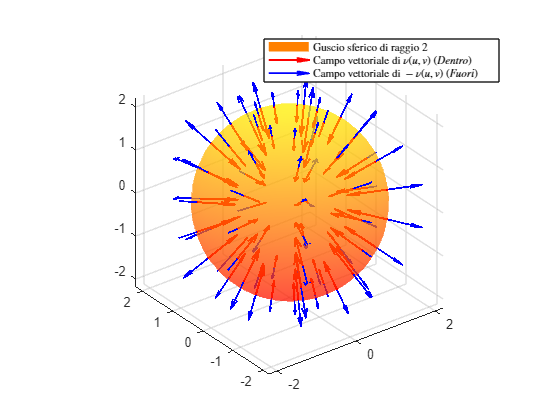

hold off